
%%0. Initialize Parameters
%% 0. Initialize Parameters DO NOT CHANGE
n = 1251;% Discretize into 1 mm seg.                  
L = 1250;% Length of bridge
x = zeros(1, L+1);
P = 400; % Total weight of train [N]

%1. SFD, BMD under train loading
clc
clear
%% 0. Initialize Parameters DO NOT CHANGE
%%_________________________________
n = 1200;               
L = 1200;
P = 400

P = 400

x = zeros(1, L+1);
for i =1:L
x(i)=i;
end
wheels = [-52 -228 -392 -568 -732 -908];
%1.SFD,BMD  %change this for the load
Pwagon=400/6;
Ploco=400/6;
SF_env=zeros(1200);
BM_env=zeros(1200);
for i = 1:1200 %should be 1:1200
  if i~=176 && i~=340 && i~=516 && i~=680 && i ~= 856
locWheel=wheels+52+i;
load=[Ploco,Ploco,Pwagon,Pwagon,Pwagon,Pwagon];
onbriwheel=zeros(1,6);
onbriload=zeros(1,6);
for k = 1:1:6
    if locWheel(k)>=0
        onbriwheel(k)=locWheel(k);
        onbriload(k)=load(k);
    end
end
RFend=sum(onbriload.*onbriwheel)/L;
RFstart=sum(onbriload)-RFend;
SF=ones(1,1200);
SF=SF.*RFstart;
for j = 6:-1:1
    if onbriwheel(j)~=0
        SF(locWheel(j):1200)=SF(locWheel(j))-onbriload(j);
    end
 end
if SF(153)<235 && SF(1000)<1500
BM=zeros(1,1200);
for o = 1:1200
    BM(o)=sum(SF(1:o));
%I FOUND THAT SOMEHOW, MY DATA ARE MORE THAN THE ACTUAL BY .08
%CONSIDER THIS AS A CORRECTION FACTOR?
%A MORE RESONABLE EXPLAINATION IS THAT THE ERROR IS CAUSED BY THE SLIGHT
%DIFFERENCE  IN THE SF CALCULATED BY APPROX AND ACTUAL SF.  MY ALGOTHRITHM
%PRODUCES THIS MUCH ERROR
end
subplot(5,1,1)
plot(SF,"b")
hold on
ABSSF=abs(SF);
subplot(5,1,2)
plot(ABSSF,"b")
hold on
%%_________________________
%THX Chat GPT
SF_env(:,i) = SF; % Assigns the entire SF vector to the i-th column of SF_env
%BM_env(:,i) = BM; % Assigns the entire BM vector to the i-th column of BM_env
%%__________________________
end
  end
end
title(subplot(5,1,1),"SFD")
title(subplot(5,1,2),"SFD-ABS")
for i = 1:1200 %should be 1:1200
%176,340
if i~=176 && i~=340 && i~=516 && i~=680 && i ~= 856
locWheel=wheels+52+i;
load=[Ploco,Ploco,Pwagon,Pwagon,Pwagon,Pwagon];
onbriwheel=zeros(1,6);
onbriload=zeros(1,6);
for k = 1:1:6
    if locWheel(k)>=0
        onbriwheel(k)=locWheel(k);
        onbriload(k)=load(k);
    end
end
RFend=sum(onbriload.*onbriwheel)/L;
RFstart=sum(onbriload)-RFend;
SF=ones(1,1200);
SF=SF.*RFstart;
for j = 6:-1:1
    if onbriwheel(j)~=0
        SF(locWheel(j):1200)=SF(locWheel(j))-onbriload(j);
    end
 end
if SF(153)<225
BM=zeros(1,1200);
for o = 1:1200
    BM(o)=sum(SF(1:o));
end
subplot(5,1,3)
plot(BM,"r")
ABSSF=abs(SF);
%plot(ABSSF,"b")
hold on
%%_________________________
%THX Chat GPT
SF_env(:,i) = ABSSF; % Assigns the entire SF vector to the i-th column of SF_env
BM_env(:,i) = BM; % Assigns the entire BM vector to the i-th column of BM_env
%%__________________________
end
end
end
SF_env

SF_env =     0.0556   66.5556   66.5000   66.4444   66.3889   66.3333   66.2778   66.2222   66.1667   66.1111   66.0556   66.0000   65.9444   65.8889   65.8333   65.7778   65.7222   65.6667   65.6111   65.5556   65.5000   65.4444   65.3889   65.3333   65.2778   65.2222   65.1667   65.1111   65.0556   65.0000   64.9444   64.8889   64.8333   64.7778   64.7222   64.6667   64.6111   64.5556   64.5000   64.4444   64.3889   64.3333   64.2778   64.2222   64.1667   64.1111   64.0556   64.0000   63.9444   63.8889
    0.0556    0.1111   66.5000   66.4444   66.3889   66.3333   66.2778   66.2222   66.1667   66.1111   66.0556   66.0000   65.9444   65.8889   65.8333   65.7778   65.7222   65.6667   65.6111   65.5556   65.5000   65.4444   65.3889   65.3333   65.2778   65.2222   65.1667   65.1111   65.0556   65.0000   64.9444   64.8889   64.8333   64.7778   64.7222   64.6667   64.6111   64.5556   64.5000   64.4444   64.3889   64.3333   64.2778   64.2222   64.1667   64.1111   64.0556   64.0000   63.9444

BM_env;
SF_env_max=zeros(1,1200);
BM_env_max=zeros(1,1200);
for i = 1:1200
SF_env_max(i)=max(SF_env(i,:));
BM_env_max(i)=max(BM_env(i,:));
end
SF_TL_max=max(max(SF_env))

SF_TL_max = 257.3333

BM_TL_max=max(max(BM_env))

BM_TL_max = 6.9260e+04

title(subplot(5,1,3),"BMD")




SF_BM_max_loc=[0 0;0 0]

SF_BM_max_loc =      0     0
     0     0


for i = 1:1200
  for j = 1:1200
      if SF_env(i,j)==SF_TL_max
          SF_BM_max_loc(1,:)=[i,j]
      end
      if BM_env(i,j)==BM_TL_max
          SF_BM_max_loc(2,:)=[i,j]
      end
  end
end

SF_BM_max_loc =            0           0
         556        1073


SF_BM_max_loc =         1200        1200
         556        1073




subplot(5,1,4)
plot(SF_env_max,"black")
title("Max ABSSF")
subplot(5,1,5)
plot(BM_env_max,"black")
title("Max BM")
BM_env(580,1097)

ans = 6.9060e+04






%2. Define Bridge Parameters
% define parameters
% xc = [0 400 800 L] % places of cross section area change
% tfw = [80 80 80 80] % top flange width
% tft = [1.27 1.27 1.27 1.27]% top flange thicknes
% bfw = [80 80 80 80] % bottom flange width
% bft = [1.27 1.27 1.27 1.27] % bottom flange thickness
% h = [60 60 60 60]
SF_TL_max = 200

SF_TL_max = 200



x1=[10 10 0 0 100 100 90 90]

x1 =     10    10     0     0   100   100    90    90


y1=[0 75 75 76.27 76.27 75 75 0]

y1 =          0   75.0000   75.0000   76.2700   76.2700   75.0000   75.0000         0


x2=[11.27 11.27 16.27 16.27 83.73 83.73 88.73 88.73]

x2 =    11.2700   11.2700   16.2700   16.2700   83.7300   83.7300   88.7300   88.7300


y2=[1.27 73.73 73.73 75 75 73.73 73.73 1.27]

y2 =     1.2700   73.7300   73.7300   75.0000   75.0000   73.7300   73.7300    1.2700


xshape=polyshape({x1,x2}, {y1,y2})

xshape =   polyshape with properties:

      Vertices: [17×2 double]
    NumRegions: 1
      NumHoles: 1


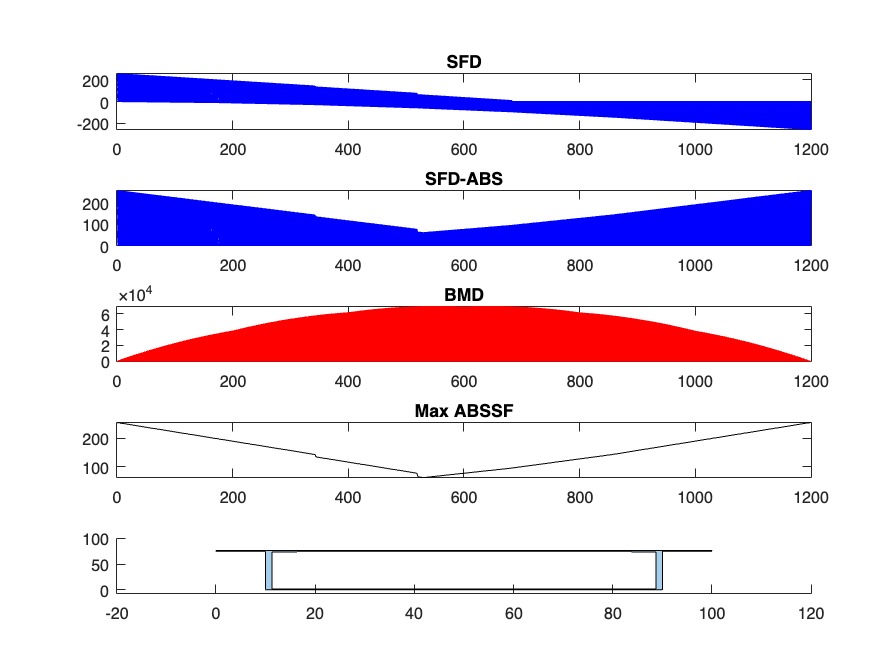

plot(xshape)



%% 3. Calculate Sectional Properties
% ybar. location of centroidal axis from the bottom
[xbar,ybar] = centroid(xshape);
xarea = area(xshape);


% I
yAxisValue = ybar

yAxisValue = 41.4311

I1 = I_1(yAxisValue) % find I for the outer shape

I1 = 3.0538e+06

I2 = I_2(yAxisValue) % find I for the inner shape

I2 = 2.6355e+06

I = I1 - I2 % total I

I = 4.1835e+05



% Calculate shear stress, use area below the y bar
% strengt of the matboard is much weacker than the tensile strength
width1 = 1.27;  % Width of the area
height1 = 41.4; % Height of the area
centroidY1 = 41.4/2; % Centroid Y of the area
dY1 = abs(centroidY1 - yAxisValue); % Distance from axis to centroid
Qy1 = 2 * width1 * height1* dY1;


width2 = 5;  % Width of the area
height2 = 1.27 ; % Height of the area
centroidY2 = 75 - height2/2; % Centroid Y of the area
dY2 = abs(centroidY2 - yAxisValue); % Distance from axis to centroid
Qy2 = 0 * width2 * height2* dY2;


width3 = 1.27;  % Width of the area
height3 = 75-41.4 ; % Height of the area
centroidY3 = 41.4 + height3/2; % Centroid Y of the area
dY3 = abs(centroidY3 - yAxisValue); % Distance from axis to centroid
Qy3 = 0* width3 * height3* dY3;


width4 = 0;  % Width of the area
height4 = 0; % Height of the area
centroidY4 = 0 + height4/2; % Centroid Y of the area
dY4 = abs(centroidY4 - yAxisValue); % Distance from axis to centroid
Qy4 = 2 * width4 * height4* dY3;


width_cent = 1.27 * 2;
Tau_cent = (Qy1 + Qy2 + Qy3 + Qy4) * SF_TL_max/(I*width_cent)

Tau_cent = 0.4103



%% 4. Calculate Applied Stress
% BM_TL_max is the maximum bending moment
% SF_TL_max is the maximum shear force
% Qcent is the Q value, or first moment of area of cross section area
% I is the second moment of area
% y_bar is the centroid in y direction (used in I calculations)
S_top = BM_TL_max*(max(y1) - ybar)/I

S_top = 5.7677

S_bot = BM_TL_max*ybar/I

S_bot = 6.8591



Qg_A1 = 100 * 1.27;
Qg_d1 = 75 - ybar + 1.27/2;
bg1 = 5 * 2; % width of two glue bars
T_glue1 = SF_TL_max*Qg_A1*Qg_d1/I/bg1

T_glue1 = 0.2077



Qg_A2 = 0;
Qg_d2 = 0;
bg2 = 0; % width of two glue bars
T_glue2 = SF_TL_max*Qg_A2*Qg_d2/I/bg2

T_glue2 = NaN



T_glue = max(T_glue1, T_glue2)

T_glue = 0.2077




%5. Material and Thin Plate Buckling Capacities
% these are given properties of the matboard and glue
E = 4000;
mu = 0.2;
S_tens = 30;
S_comp = 6;
Tau_max = 4;
Tau_gluemax = 2;


t_buck1 = 1.27 % thickness

t_buck1 = 1.2700

b_buck1 = 80 % distance between the webs

b_buck1 = 80

S_buck1 = (4 * pi^2 * E / (12*(1 - mu^2))) *(t_buck1/b_buck1)^2

S_buck1 = 3.4546



t_buck2 = 1.27 % thickness of the top flange

t_buck2 = 1.2700

b_buck2 = 10 % width of the two sides of the top flange

b_buck2 = 10

S_buck2 = (0.425 * pi^2 * E / (12*(1 - mu^2))) *(t_buck2/b_buck2)^2

S_buck2 = 23.4911



t_buck3 = 1.27*2 % twice the thickness of web

t_buck3 = 2.5400

b_buck3 = 75-41.4 % length of the web above ybar

b_buck3 = 33.6000

S_buck3 =(6 * pi^2 * E / (12*(1 - mu^2))) *(t_buck3/b_buck3)^2

S_buck3 = 117.5026



T_buck_t = 1.27 % thickness

T_buck_t = 1.2700

T_buck_b = 75-1.27 % height of web

T_buck_b = 73.7300

T_buck_a = 400% distance between diaphragms

T_buck_a = 400

T_buck = (5 * pi^2 * E / (12*(1 - mu^2))) *((T_buck_t/T_buck_b)^2 + (T_buck_t/T_buck_a)^2)

T_buck = 5.2566



%% 6. FOS
FOS_tens = S_tens/S_bot

FOS_tens = 4.3738

FOS_comp = S_comp/S_top

FOS_comp = 1.0403

FOS_shear = Tau_max/Tau_cent

FOS_shear = 9.7488

FOS_glue = Tau_gluemax/T_glue

FOS_glue = 9.6308

FOS_buck1 = S_buck1/S_top

FOS_buck1 = 0.5989

FOS_buck2 = S_buck2/S_top

FOS_buck2 = 4.0729

FOS_buck3 = S_buck3/S_top

FOS_buck3 = 20.3724

FOS_buckV = T_buck/Tau_cent

FOS_buckV = 12.8114



FOSES = [FOS_tens FOS_comp FOS_shear FOS_glue FOS_buck1 FOS_buck2 FOS_buck3 FOS_buckV]

FOSES =     4.3738    1.0403    9.7488    9.6308    0.5989    4.0729   20.3724   12.8114


%     FOS_buck1 FOS_buck2 FOS_buck3]
%% 7. Min FOS and the failure load Pfail
% minFOS = min(FOSES)
% Pf_S = min(A*S_tens A*S_comp)
% Pf_buck = I*pi^2*E
% Pf = min(Pf_s Pf_buck)
%% 8. Vfail and Mfail
Mf_tens = FOS_tens*BM_TL_max

Mf_tens = 3.0293e+05

Mf_comp = FOS_comp*BM_TL_max

Mf_comp = 7.2049e+04

Vf_shear = FOS_shear*SF_TL_max

Vf_shear = 1.9498e+03

Vf_glue = FOS_glue*SF_TL_max

Vf_glue = 1.9262e+03

Mf_buck1 = FOS_buck1*BM_TL_max

Mf_buck1 = 4.1483e+04

Mf_buck2 = FOS_buck2*BM_TL_max

Mf_buck2 = 2.8209e+05

Mf_buck3 = FOS_buck3*BM_TL_max

Mf_buck3 = 1.4110e+06

Vf_buckV = FOS_buckV*SF_TL_max

Vf_buckV = 2.5623e+03

V_fail = [Vf_shear Vf_glue Vf_buckV]

V_fail = 1.0e+03 *

    1.9498    1.9262    2.5623


M_fail = [Mf_tens, Mf_comp, Mf_buck1, Mf_buck2, Mf_buck3]

M_fail = 1.0e+06 *

    0.3029    0.0720    0.0415    0.2821    1.4110


V_fail_min = min(V_fail)

V_fail_min = 1.9262e+03

M_fail_min = min(M_fail)

M_fail_min = 4.1483e+04





F_load = min(FOSES) * P

F_load = 239.5796

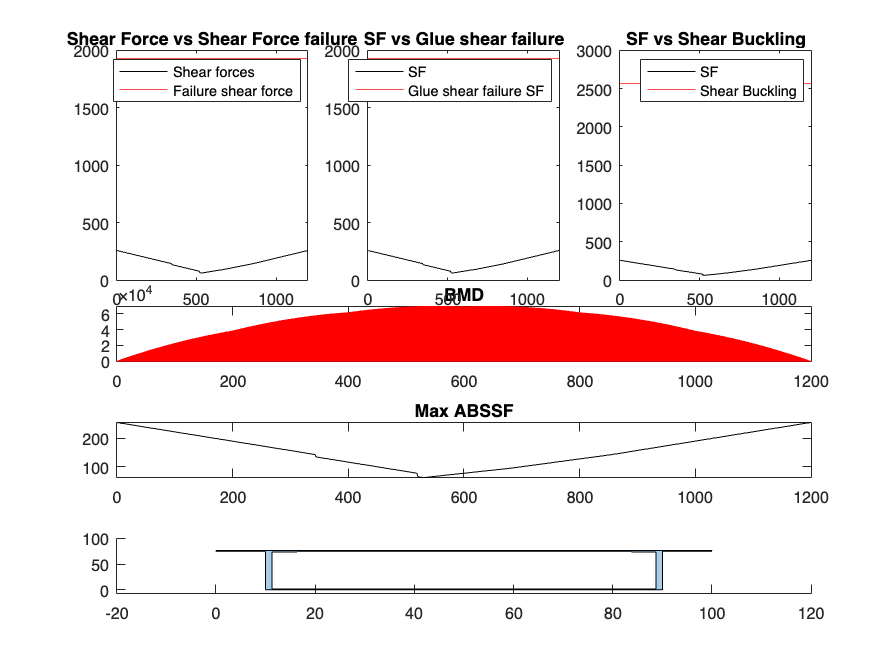



%% 9. Output plos of Vfail and Mfail
% subplot(2,3,1)
% hold on; grid on; grid minor;
% plot(x, Vf_shear, 'r')
% plot(x, -Vf_shear.* SFD, 'r')
% plot(x, SFDi, 'k');
% plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Matboard Shear Failure')
% xlabel('Distance along bridge (mm)')
% ylabel('Shear Force (N)')

subplot(2, 3, 1)
plot(SF_env_max,"black")
yline(V_fail_min, "red")
hold on
title("Shear Force vs Shear Force failure")
legend("Shear forces", "Failure shear force")
hold off
subplot(2,3,2)
plot(SF_env_max,"black")
title("SF vs Glue shear failure")
hold on
yline(Vf_glue, "red")
legend("SF", "Glue shear failure SF")
subplot(2,3,3)
plot(SF_env_max,"black")
title("SF vs Shear Buckling")
hold on
yline(Vf_buckV, "red")
legend("SF", "Shear Buckling")

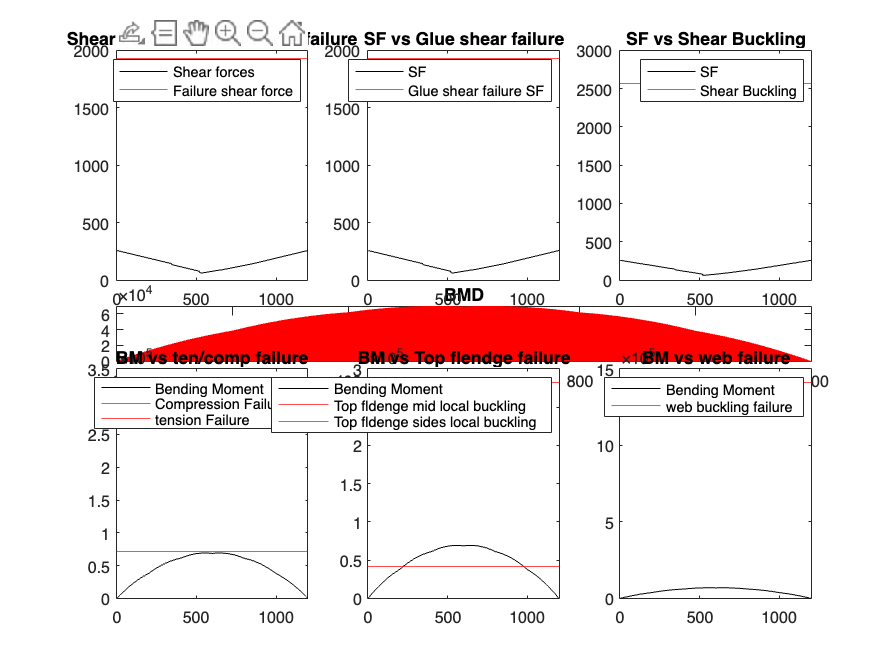

subplot(2,3,4)
plot(BM_env_max,"black")
title("BM vs ten/comp failure")
hold on
yline(Mf_comp, "red")
yline(Mf_tens, "red")
legend("Bending Moment", "Compression Failure","tension Failure")
subplot(2,3,5)
plot(BM_env_max,"black")
title("BM vs Top flendge failure")
hold on
yline(Mf_buck1, "red")
yline(Mf_buck2, "red")
legend("Bending Moment", "Top fldenge mid local buckling","Top fldenge sides local buckling")
subplot(2,3,6)
plot(BM_env_max,"black")
title("BM vs web failure")
hold on
yline(Mf_buck3, "red")
legend("Bending Moment", "web buckling failure")




%6. Functions used

function Iy = I_1(yAxisValue)
  % This function calculates the second moment of area of an "I" shaped polyshape
  % about a horizontal axis at y = yAxisValue.
   % Segment 1: Top Flange (10, 76.27) to (100, 76.27)
  width1 = 100;  % Width of the top flange
  height1 = 1.27; % Height of the top flange
  centroidY1 = 75 + 1.27/2; % Centroid Y of the top flange
  dY1 = abs(centroidY1 - yAxisValue); % Distance from axis to centroid
  Iy1 = (width1 * height1^3 / 12) + (width1 * height1 * dY1^2); % Second moment of area of the top flange




  % Segment 2: Bottom Flange (10, 0) to (100, 0)
  width2 = 80;  % Width of the bottom flange
  height2 = 75 ; % Height of the bottom flange
  centroidY2 = 75/2; % Centroid Y of the bottom flange
  dY2 = abs(centroidY2 - yAxisValue); % Distance from axis to centroid
  Iy2 = (width2 * height2^3 / 12) + (width2 * height2 * dY2^2); % Second moment of area of the bottom flange




  % Sum the moments of all segments
  Iy = Iy1 + Iy2;
end


function Iy = I_2(yAxisValue)
  % This function calculates the second moment of area of an "I" shaped polyshape
  % about a horizontal axis at y = yAxisValue.
   % Segment 1: Top Flange (16.27, 75) to (83.73, 75)
  width1 = 83.73 - 16.27;  % Width of the top flange
  height1 = 1.27; % Height of the top flange
  centroidY1 = 75 - 1.27/2; % Centroid Y of the top flange
  dY1 = abs(centroidY1 - yAxisValue); % Distance from axis to centroid
  Iy1 = (width1 * height1^3 / 12) + (width1 * height1 * dY1^2); % Second moment of area of the top flange




  % Segment 2: Bottom Flange (11.27, 0) to (88.73, 0)
  width2 = 88.73 - 11.27;  % Width of the bottom flange
  height2 = 75-2*1.27; % Height of the bottom flange
  centroidY2 = (75) / 2; % Centroid Y of the bottom flange
  dY2 = abs(centroidY2 - yAxisValue); % Distance from axis to centroid
  Iy2 = (width2 * height2^3 / 12) + (width2 * height2 * dY2^2); % Second moment of area of the bottom flange




  % Sum the moments of all segments
  Iy = Iy1 + Iy2;
end





